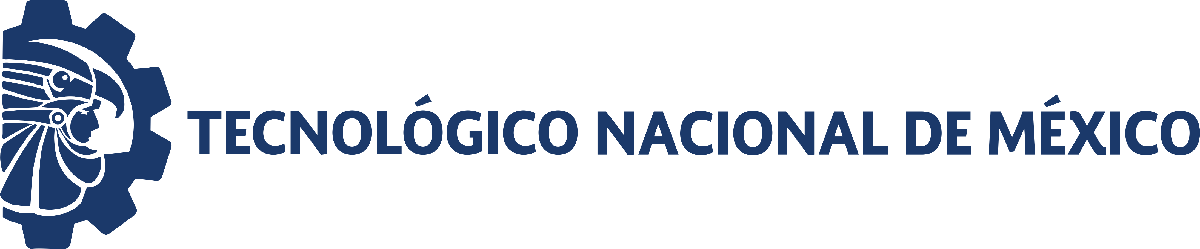                                 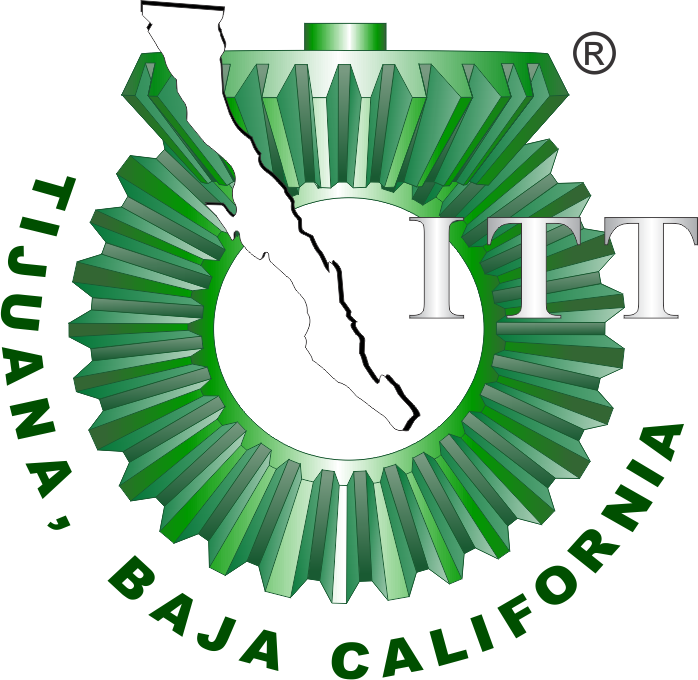

# Práctica tres: Sistema musculoesquelético

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

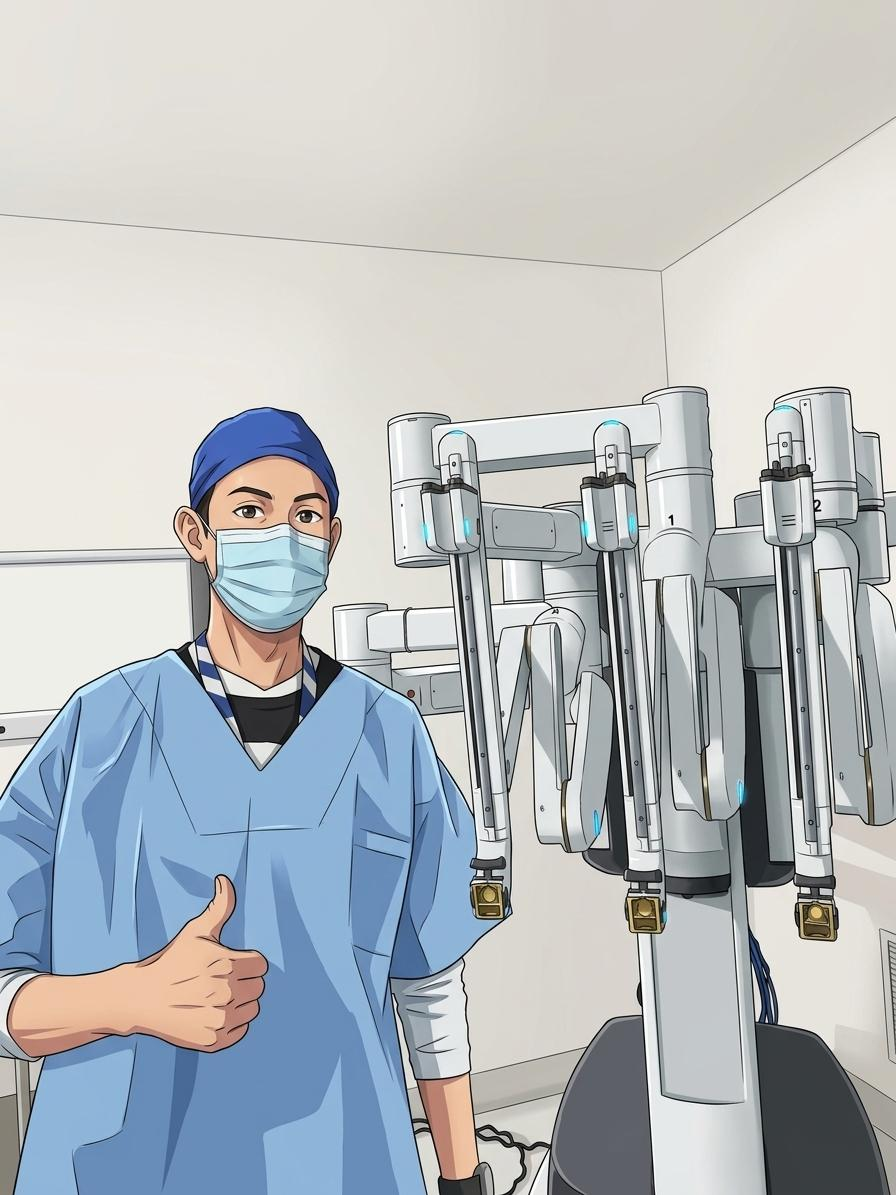

Nombre del alumno: Ernesto Jáuregui Bogarin

Número de control: 23212203

Correo institucional: l23212203**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('Sistema_Practica3')
parameters.StopTime = '10';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';

## Respuesta al impulso unitario

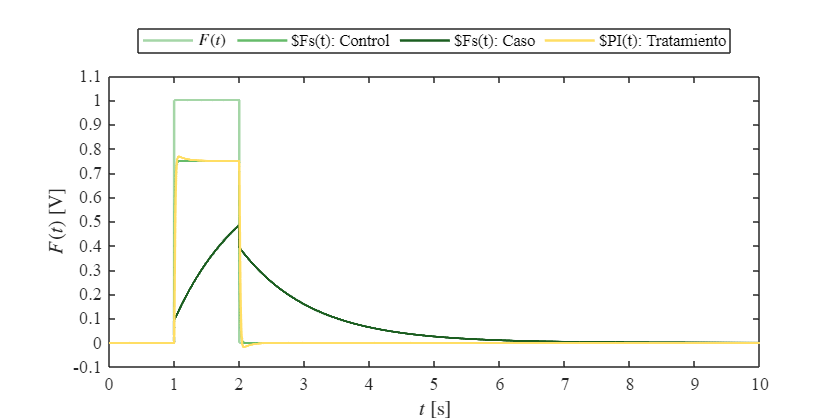

X = sim('Sistema_Practica3',parameters);
plotsignals(X.t,X.F,X.Fsx,X.Fsy,X.PID,'Control y caso');

## Función: Respuesta a las señales

function plotsignals(t, F, Fsx, Fsy, PID, signal)
    set(figure(),'color','w')
    set(gcf,'units','inches','position',[1,1,7,3.5])
    set(gca,'fontname','times new roman','fontsize',11)
    hold on; grid off;box on;
    clr1 = [165,214,167]/255;
    clr2 = [102,187,106]/255;
    clr3 = [27,94,32]/255;
    clr4 = [255,222,100]/255;
    order = [clr1;clr2;clr3;clr4];colororder(order)


    if signal == "Control y caso"        
        plot(t,F,'-',t,Fsx,'-',t,Fsy,'-',t,PID,'-','LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1e3:length(t));
        L = legend('$F(t)$','$Fs(t): Control','$Fs(t): Caso','$PI(t): Tratamiento'); 
    end     

    set(L,'interpreter','latex','location','northoutside','orientation','horizont al')    
    %title(L,[signal,' input'])    
    xlabel('$t$ [s]','interpreter','latex')    
    ylabel('$F(t)$ [V]','interpreter','latex')    
    xlim([0 10]); xticks(0:1:15)    
    ylim([-0.1 1.1]); yticks(-0.1:0.1:1.1)

exportgraphics(gcf,[signal,'_matlab.pdf'],'ContentType','vector')
end
